clear all;
clc;
close all;

i=sqrt(-1); % imaginary unit
rng(123) % set constant seed
addpath('C:\Users\johnb\Documents\fmri-research\kspace-simulator\data')
addpath('C:\Users\johnb\Documents\fmri-research\kspace-simulator\functions')

Test function. TR and TE taken from "Incorporating relaxivities..."

load M0Map96.mat
load T1Map96.mat
load T2Map96.mat

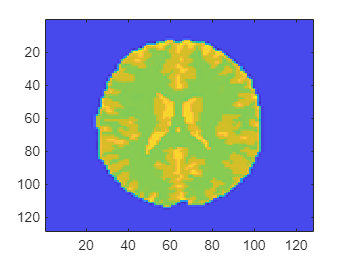

load M0Map128.mat
%M0Map = rot90(M0Map);
figure;
imagesc(squeeze(M0Map(:,:,64)));

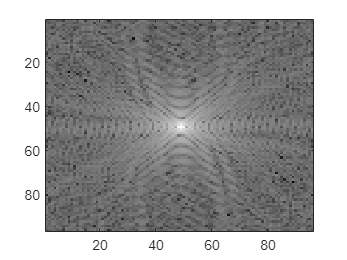

load saves\testks.mat

figure;
imagesc(log10(abs(ks)))
colormap('gray')

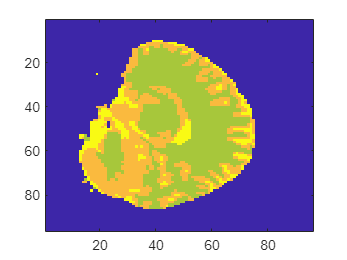


test2 = squeeze(test.M0Map(:,40,:));

figure;
imagesc(test2)

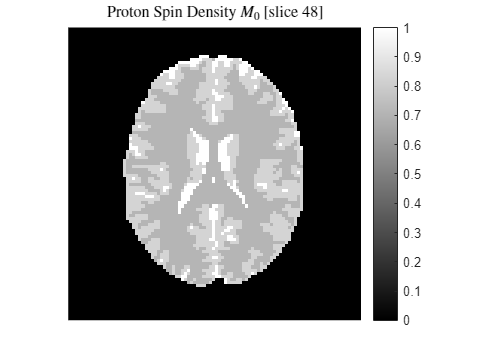


slice = 48;
rec_size = length(M0Map);

M0=M0Map(:,:,slice);
t2star=T2Map(:,:,slice);
t1=T1Map(:,:,slice);
deltaB = repmat(linspace(-2.5,2.5,rec_size)*10e-7,rec_size,1);
deltaB = deltaB + t1./(10^8);

figure;
imagesc(abs(M0), [0 1])
axis image; axis off;
colormap('gray'); colorbar;
title(['Proton Spin Density $M_0$ [slice ', num2str(slice),']'],Interpreter='latex')

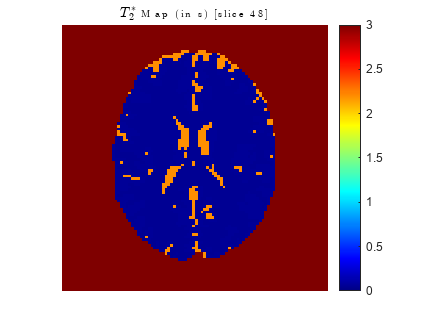

%exportgraphics(gcf,'figures/MAP-prot-spin-den.png','Resolution',600)

figure;
imagesc(abs(t2star),[0 3])
axis image; axis off;
colormap('jet'); colorbar;
title(['$T_2^*$ Map (in s) [slice ', num2str(slice),']'],Interpreter='latex')

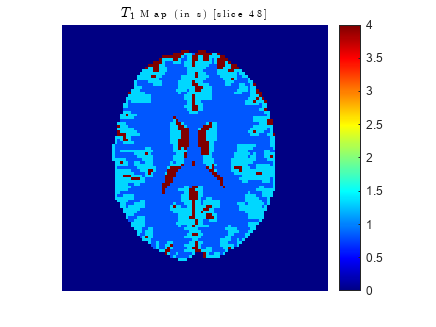

%exportgraphics(gcf,'figures/MAP-t2star.png','Resolution',600)

figure;
imagesc(abs(t1), [0 4])
axis image; axis off;
colormap('jet'); colorbar;
title(['$T_1$ Map (in s) [slice ', num2str(slice),']'],Interpreter='latex')

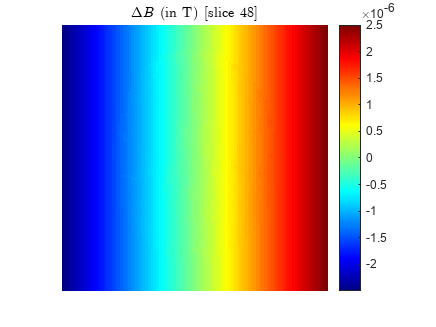

%exportgraphics(gcf,'figures/MAP-t1.png','Resolution',600)

figure;
imagesc(deltaB)
axis image; axis off;
colormap('jet'); colorbar;
title(['$\Delta B$ (in T) [slice ', num2str(slice),']'],Interpreter='latex')

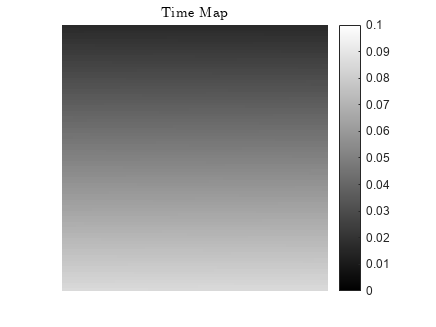

%exportgraphics(gcf,'figures/MAP-deltaB.png','Resolution',600)

% create time map
eesp = 0.000720;
deltaT = 1/(2*125*10^3);
extras=0;
TE=50;

timeMap = zeros(rec_size,rec_size);
count = 0;
for row = 1:rec_size
    for col=1:rec_size
        if mod(row,2)==1
            timeMap(row,col)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        elseif mod(row,2)==0
            timeMap(row,rec_size-col+1)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        end
    end
end
timeMapMsec = timeMap*1000;
init_t = TE - timeMapMsec(rec_size/2-1,rec_size);
timeMap = timeMap + init_t/1000;

figure;
imagesc(timeMap,[0,0.1])
axis image; axis off;
colormap('gray'); colorbar;
title('Time Map',Interpreter='latex')

%exportgraphics(gcf,'figures/MAP-time.png','Resolution',600)

TR=1; % 1 second
TE=50e-03; % 50 ms
% gamma is gyromagnetic ratio 42 MHz/Tesla
gamma=42e06; % gyromagnetic ratio
FOV=240e-03; % FOV in mm

% test cartesian kx, ky
[kx,ky] = meshgrid(-rec_size/2:rec_size/2-1,-rec_size/2:rec_size/2-1);

%test = kspace(M0,t2star,t1,deltaB,timeMap,TR,kx,ky);
test = kspace(M0,-1,-1,deltaB,TE,TR,kx,ky);


% add jsut a TINY bit of noise to make phase plots nicer
normalVar=0.5
noiseK = sqrt(normalVar)*(randn(size(test))+sqrt(-1)*randn(size(test)));
testN = test + noiseK;



figure;
imagesc(log10(abs(testN)+1))
axis image; axis off;
colormap('gray'); %colorbar
%title('Simulated $k$-Space',Interpreter='latex')
exportgraphics(gcf,'figures/cart-kspace-all-haha.png','Resolution',600)

test2=ifft2(fftshift(testN));
figure;
imagesc(abs(test2))
axis image; axis off;
colormap('gray');% colorbar
%title('Simulated Magnitude',Interpreter='latex')
%exportgraphics(gcf,'figures/cart-mag-deltaB.png','Resolution',600)

figure;
imagesc(angle(test2))
axis image; axis off;
colormap('gray');% colorbar
%title('Simulated Phase',Interpreter='latex')
%exportgraphics(gcf,'figures/cart-phase-deltaB.png','Resolution',600)

figure;
imagesc(real(test2))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Real',Interpreter='latex')
%exportgraphics(gcf,'figures/cart-real.png','Resolution',600)

figure;
imagesc(imag(test2))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Imaginary',Interpreter='latex')
%exportgraphics(gcf,'figures/cart-imag.png','Resolution',600)

mask = (abs(test2)./max(abs(test2),[],'all')) > (1/10);
figure;
imagesc(mask)
colorbar

Test function ***In Polar***. TR and TE taken from "Incorporating relaxivities..."

load SpinDenMap.mat
load T1Map.mat
load T2Map.mat

M0=SpinDenMap(:,:,40);
t2star=T2Map(:,:,40);
t1=T1Map(:,:,40);
deltaB = repmat(linspace(-2.5,2.5,96)*10e-7,96,1);
deltaB = deltaB + t1./(10^8);

TR=1; % 1 second
TE=50e-03; % 50 ms
gamma=42e06; % gym
FOV=240e-03; % FOV in mm

% test polar kx, ky
rec_size=96;
nsamp = rec_size;
nspokes = ceil(pi/2 * rec_size); % pi/2 * sampling density
% create polar k-space
xr=[-nsamp/2:1:nsamp/2-1]';
angles = linspace(0,180,nspokes+1);
angles(end)=[];
kx=zeros(nsamp,nspokes);
ky=zeros(nsamp,nspokes);
for m=1:nspokes
    kx(:,m) = xr*cosd(angles(m));
    ky(:,m) = xr*sind(angles(m));
end
rampdcf = 1/nspokes + (kx.^2 + ky.^2).^(0.5);

% create time map
eesp = 0.000720;
deltaT = 1/(2*125*10^3);
extras=0;
TE=50;
%TE = TE * 151/96;
timeMap = zeros(nspokes,nsamp);
count = 0;
for row = 1:nspokes
    for col = 1:nsamp
        if mod(row,2)==1
            timeMap(row,col)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        elseif mod(row,2)==0
            timeMap(row,nsamp-col+1)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        end
    end
end
timeMapMsec = timeMap*1000;
init_t = TE - timeMapMsec(floor(nspokes/2)-1,nsamp); % get middle time
timeMap = (timeMap + init_t/1000)';

figure;
imagesc(timeMap)
colorbar

TE=50e-03;
%test = kspace(M0,t2star,t1,deltaB,timeMap,TR,kx,ky);
test = kspace(M0,t2star,t1,deltaB/10,TE,TR,kx,ky);


normalVar=0.5
noiseK = sqrt(normalVar)*(randn(size(test))+sqrt(-1)*randn(size(test)));
testN = test + noiseK;

figure;
imagesc(abs(testN))
axis image; axis off;
colormap('gray'); %colorbar
%title('Simulated Polar $k$-Space',Interpreter='latex')
%exportgraphics(gcf,'figures/polar-kspace.png','Resolution',600)

figure;
imagesc(abs(testN.*rampdcf))
axis image; axis off; colorbar
colormap('gray'); %colorbar
%title('Simulated Polar $k$-Space (filtered)',Interpreter='latex')
%exportgraphics(gcf,'figures/polar-kspace-ramp.png','Resolution',600)

surf()

figure;
surf(kx, -ky, abs(testN).*rampdcf, EdgeAlpha=0)
colormap('gray');
axis image; view(2); axis off;
%exportgraphics(gcf,'figures/pk-ramp.png','Resolution',600)

% finufft reconstruction
kxx = rescale(kx(:),-1*pi,1*pi);
kyy = rescale(ky(:),-1*pi,1*pi);
isign = -1; tol = 1e-5; 
ms=4*rec_size; mt=4*rec_size;
opts.modeord = 1; opts.chkbnds = 0;
test2 = finufft2d1(kxx,kyy,test.*rampdcf,isign,tol,ms,mt,opts);
test2 = rot90(transpose(reshape(test2,ms,mt)),2);
test2 = (1/nsamp/nspokes)*test2(1:rec_size,1:rec_size); % or (1/rec_size/rec_size)?


figure;
imagesc(abs(test2))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Polar Magnitude',Interpreter='latex')
%exportgraphics(gcf,'figures/polar-mag-finufft.png','Resolution',600)

figure;
imagesc(angle(test2))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Polar Phase',Interpreter='latex')
%exportgraphics(gcf,'figures/polar-phase-finufft.png','Resolution',600)

figure;
imagesc(real(test2))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Polar Real',Interpreter='latex')
%exportgraphics(gcf,'figures/polar-real.png','Resolution',600)

figure;
imagesc(imag(test2))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Polar Imag',Interpreter='latex')
%exportgraphics(gcf,'figures/polar-imag.png','Resolution',600)

HAPI

load SpinDenMap.mat
load T1Map.mat
load T2Map.mat

rec_size=96;
M0=SpinDenMap(:,:,40);
t2star=T2Map(:,:,40);
t1=T1Map(:,:,40);
deltaB = repmat(linspace(-2.5,2.5,rec_size)*10e-7,rec_size,1);
deltaB = deltaB + t1./(10^8);

TR=1; % 1 second
TE=50e-03; % 50 ms
gamma=100e-03; % I have no idea what this should be close to.
FOV=240e-03; % FOV in mm

% test polar kx, ky
nsamp = 512;

% create polar k-space
xr=[-nsamp/2:1:nsamp/2-1]';
angles = [14 77 -36 -7];
nspokes=length(angles);

kx=zeros(nsamp,nspokes);
ky=zeros(nsamp,nspokes);
for m=1:nspokes
    kx(:,m) = xr*cosd(angles(m));
    ky(:,m) = xr*sind(angles(m));
end
rampdcf = 1/nspokes + (kx.^2 + ky.^2).^(0.5);

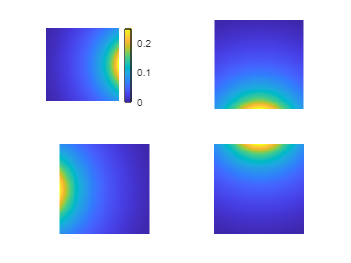

reconX=96; reconY=96;
Ncoils=4; startAngle=0;
delta=360/Ncoils;

r=min(reconX,reconY)*0.75;
[x,y]=meshgrid(-reconY/2:reconY/2-1,-reconX/2:reconX/2-1);
d=zeros(reconY,reconX,Ncoils);

for c=1:Ncoils
    d(:,:,c) = rescale(((x-r*cosd(startAngle+(c-1)*delta)).^2 + (y-r*sind(startAngle+(c-1)*delta)).^2).^(-1/2),0,1/Ncoils);
end

figure;
subplot(2,2,1)
imagesc(d(:,:,1))
axis image; axis off
colorbar
subplot(2,2,2)
imagesc(d(:,:,2))
axis image; axis off
subplot(2,2,3)
imagesc(d(:,:,3))
axis image; axis off
subplot(2,2,4)
imagesc(d(:,:,4))
axis image; axis off

c = generate_coils(96,96,8,0);
figure;
subplot(2,2,1)
imagesc(c(:,:,1))
axis image; axis off
subplot(2,2,2)
imagesc(c(:,:,2))
axis image; axis off
subplot(2,2,3)
imagesc(c(:,:,3))
axis image; axis off
subplot(2,2,4)
imagesc(c(:,:,4))
axis image; axis off


sumC = sum(c,3);
figure;
imagesc(sumC)
colorbar